### 1. 生成事件映射图（二维）MNIST_diff

将图片（归一化到0-1）进行某个方向的平移后，与原图像做差分，得到的结果叠加上噪声（ground truth不用加噪），然后对加噪差分图像进行极性化操作，即大于0.5的为1，即ON事件，小于-0.5的为-1，即OFF事件，其余为0，即未激发状态。（暂时不考虑时间戳的问题）

导入数据

% 加载数据并归一化
clear
clc
load mnist_uint8;
train_x = double(train_x)/255;
test_x  = double(test_x)/255;
train_labels = double(train_y);
test_labels  = double(test_y);

数据处理

% reshape为二维,并转置为正放图片
train_x = reshape(train_x,[60000, 28, 28]);
train_x = permute(train_x, [1,3,2]);

test_x = reshape(test_x,[10000, 28, 28]);
test_x = permute(test_x, [1,3,2]);


%% 移位差分极性化-train_x
train_shift = zeros(size(train_x)); %移位
train_diff = zeros(size(train_x));  %差分

train_shift(1:10000,:,:)=circshift(train_x(1:10000,:,:),[0,0,2]); %右移2像素
train_shift(10001:20000,:,:)=circshift(train_x(10001:20000,:,:),[0,0,-2]); %左移2像素
train_shift(20001:30000,:,:)=circshift(train_x(20001:30000,:,:),[0,2,0]); %下移2像素
train_shift(30001:40000,:,:)=circshift(train_x(30001:40000,:,:),[0,-2,0]); %上移2像素
train_shift(40001:45000,:,:)=circshift(train_x(40001:45000,:,:),[0,1,1]); %右上移1像素
train_shift(45001:50000,:,:)=circshift(train_x(45001:50000,:,:),[0,1,-1]); %右下移1像素
train_shift(50001:55000,:,:)=circshift(train_x(50001:55000,:,:),[0,-1,-1]); %左上移2像素
train_shift(55001:60000,:,:)=circshift(train_x(55001:60000,:,:),[0,-1,1]); %左下移2像素

train_diff = train_shift - train_x; %差分

train_diff_gt = train_diff; %不加噪，ground truth
train_diff_gt(train_diff_gt>=0.5) = 1;
train_diff_gt(train_diff_gt<=-0.5) = -1;
train_diff_gt(train_diff_gt>-0.5 & train_diff_gt<0.5) = 0;  %极性化

train_diff = train_diff + 0.25*randn(size(train_diff)); %加噪
train_diff(train_diff>=0.5) = 1;
train_diff(train_diff<=-0.5) = -1;
train_diff(train_diff>-0.5 & train_diff<0.5) = 0;  %极性化

%% test_x同上操作
test_shift = zeros(size(test_x)); %移位
test_diff = zeros(size(test_x));  %差分

test_shift(1:1250,:,:)=circshift(test_x(1:1250,:,:),[0,0,2]); %右移2像素
test_shift(1251:2500,:,:)=circshift(test_x(1251:2500,:,:),[0,0,-2]); %左移2像素
test_shift(2501:3750,:,:)=circshift(test_x(2501:3750,:,:),[0,2,0]); %下移2像素
test_shift(3751:5000,:,:)=circshift(test_x(3751:5000,:,:),[0,-2,0]); %上移2像素
test_shift(5001:6250,:,:)=circshift(test_x(5001:6250,:,:),[0,1,1]); %右上移2像素
test_shift(6251:7500,:,:)=circshift(test_x(6251:7500,:,:),[0,1,-1]); %右下移2像素
test_shift(7501:8750,:,:)=circshift(test_x(7501:8750,:,:),[0,-1,-1]); %左上移2像素
test_shift(8751:10000,:,:)=circshift(test_x(8751:10000,:,:),[0,-1,1]); %左下移2像素

test_diff = test_shift - test_x; %差分

test_diff_gt = test_diff; %不加噪，ground truth
test_diff_gt(test_diff_gt>=0.5) = 1;
test_diff_gt(test_diff_gt<=-0.5) = -1;
test_diff_gt(test_diff_gt>-0.5 & test_diff_gt<0.5) = 0;  %极性化

test_diff = test_diff + 0.25*randn(size(test_diff)); %加噪
test_diff(test_diff>=0.5) = 1;
test_diff(test_diff<=-0.5) = -1;
test_diff(test_diff>-0.5 & test_diff<0.5) = 0;  %极性化



保存数据

save('MNIST_diff_train.mat', 'train_diff', 'train_diff_gt')
save('MNIST_diff_test.mat', 'test_diff', 'test_diff_gt')
save('MNIST_diff_labels.mat', 'train_labels', 'test_labels')

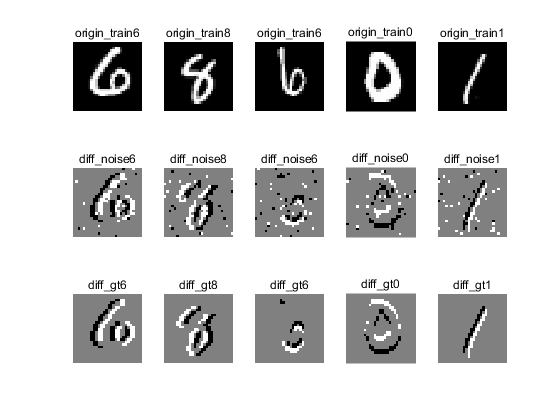

%查看验证

figure(1)

for k=1:5
num_str = num2str(find(train_labels(k*8000+5,:))-1);
    subplot(3,5,k)
    pic = (squeeze(train_x(k*8000+5,:,:)));
    imshow(pic,[]), title(['origin\_train',num_str])
    subplot(3,5,k+5)
    pic = (squeeze(train_diff(k*8000+5,:,:)));
    imshow(pic,[]), title(['diff\_noise',num_str])
    subplot(3,5,k+10)
    pic = (squeeze(train_diff_gt(k*8000+5,:,:)));
    imshow(pic,[]), title(['diff\_gt',num_str])
end

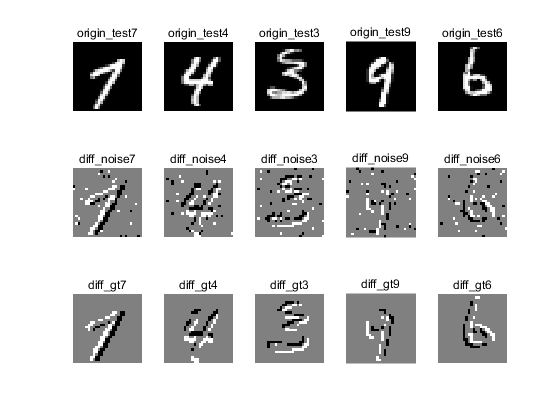


figure(2)
for k=1:5
    num_str = num2str(find(test_labels(k*1800+5,:))-1);
    subplot(3,5,k)
    pic = (squeeze(test_x(k*1800+5,:,:)));
    imshow(pic,[]), title(['origin\_test', num_str])    
    subplot(3,5,k+5)
    pic = (squeeze(test_diff(k*1800+5,:,:)));
    imshow(pic,[]), title(['diff\_noise', num_str])
    subplot(3,5,k+10)
    pic = (squeeze(test_diff_gt(k*1800+5,:,:)));
    imshow(pic,[]), title(['diff\_gt', num_str])
end

### 2. 生成事件序列

场景中常见的目标一般为刚性目标，即各部分同时发生变化，相应的，各个部分的像素触发的事件也基本同时产生。由于事件相机采用按行扫描的方式来收集触发的事件

加载数据

clc
clear
load MNIST_diff_train.mat
load MNIST_diff_test.mat


num_str = num2str(find(train_labels(k*8000+5,:)-1))

num_str = '1   3   4   5   6   7   8   9  10'